clc
clear all
close all
rng(0)

# M3C Simulation

## Parameters

Simulation and control steps

Tf = 0.5;      % Total simulation time
Ts = 100e-6;    % Sampling time
Ns = Tf/Ts      % Number of sampling steps

Ns = 5000

Ti = 10e-6;	    % Integration step
Ni = Ts/Ti      % Number of integration steps between each ISR (Interrupt Service Routine)

Ni = 10

Tsim = linspace(0, Tf, Ns);

Ax0 = 7000;
Ay0 = 5000;
fx0 = 50;
fy0 = 50;
wx0 = 2*pi*fx0;
wy0 = 2*pi*fy0;

[ix_max, iy_max, is_max, vo_max, vB_max, VCdiff] = max_values(Ax0, Ay0)

ix_max = 71.4286

iy_max = 100

is_max = 142.8571

vo_max = 6000

vB_max = 12000

VCdiff = 0.0020

## External system (IOGrid)

Specifications

specsIOGrid = struct();

specsIOGrid.Ti = Ti;
specsIOGrid.Ax = Ax0;
specsIOGrid.fx = fx0;
specsIOGrid.Ay = Ay0;
specsIOGrid.fy = fy0;

Initial values

init_valsIOGrid = struct();

init_valsIOGrid.gx0 = 0;
init_valsIOGrid.gy0 = 0;

Create object

IOGrid = ClassIOGrid(specsIOGrid, init_valsIOGrid)

IOGrid =   ClassIOGrid with properties:

     Ti: 1.0000e-05
     Ax: 7000
     Ay: 5000
     fx: 50
     fy: 50
     wx: 314.1593
     wy: 314.1593
     gx: 0
     gy: 0
    vxy: [6×1 double]

## Modular Multilevel Matrix Converter (M3C)

Specifications

specsM3C = struct();

specsM3C.Ti  = Ti;       % Integration step
specsM3C.R   = 1e-3;     % Branch resistance
specsM3C.L   = 20e-3;    % Branch inductance
specsM3C.Csm = 20e-3;    % Submodule capacitance
specsM3C.Nsm = 4;        % Submodules per cluster
specsM3C.Rx  = 0.1e-3;   % Input filter resistance
specsM3C.Lx  = 1e-3;     % Input filter inductance
specsM3C.Ry  = 0.1e-3;   % Output filter resistance
specsM3C.Ly  = 1e-3;     % Output filter inductance

Initial values

init_valsM3C = struct();

init_valsM3C.is0 = zeros(9, 1);                     % Cluster current
init_valsM3C.vc0 = (vB_max + vo_max) * ones(9, 1);  % Cluster capacitor voltage

Create object

M3C = ClassM3C(specsM3C, init_valsM3C)

M3C =   ClassM3C with properties:

        A: [6×9 double]
    pinvA: [9×6 double]
        m: 9
        N: [9×4 double]
        n: 4
    pinvN: [4×9 double]
        p: 3
        q: 3
       Ti: 1.0000e-05
        R: 1.0000e-03
        L: 0.0200
      Csm: 0.0200
      Nsm: 4
        C: 0.0050
       Rx: 1.0000e-04
       Lx: 1.0000e-03
       Ry: 1.0000e-04
       Ly: 1.0000e-03
       As: [9×9 double]
       Bs: [9×9 double]
       Ad: [9×9 double]
       Bd: [9×9 double]
      ixy: [6×1 double]
       is: [9×1 double]
      pis: [9×1 double]
       iB: [9×1 double]
       iz: [9×1 double]
       ie: [4×1 double]
       vc: [9×1 double]
       Ec: [9×1 double]

## Phase Locked Loops (PLL)

[ImperixPLL](https://imperix.com/doc/implementation/synchronous-reference-frame-pll)

Specifications

xi_pll = 1/sqrt(2);
wc_pll = 100*2*pi;

specsPLL = struct();

specsPLL.Ts    = Ts;
specsPLL.kp    = 2*xi_pll*wc_pll;
specsPLL.ki    = wc_pll^2;
specsPLL.u_min = -Inf;
specsPLL.u_max = Inf;

Create objects

PLLx = ClassPLL(specsPLL)

PLLx =   ClassPLL with properties:

        g: 0
        w: 0
       Ts: 1.0000e-04
       kp: 888.5766
       ki: 3.9478e+05
    u_min: -Inf
    u_max: Inf
       b0: -868.8374
       b1: 908.3158
       a0: -1
       a1: 1
      e_t: 0
    e_t_1: 0
      u_t: 0
    u_t_1: 0

PLLy = ClassPLL(specsPLL)

PLLy =   ClassPLL with properties:

        g: 0
        w: 0
       Ts: 1.0000e-04
       kp: 888.5766
       ki: 3.9478e+05
    u_min: -Inf
    u_max: Inf
       b0: -868.8374
       b1: 908.3158
       a0: -1
       a1: 1
      e_t: 0
    e_t_1: 0
      u_t: 0
    u_t_1: 0

## TEB PI and Filter design

Plant model

% (Mean cluster capacitor voltage)/(Input current) transfer function
vc_mean_ref = vB_max + vo_max;
k_teb       = Ax0/(6*vc_mean_ref) / M3C.C

k_teb = 12.9630

G_teb       = k_teb*tf(1, [1, 0])


G_teb =
 
  12.96
  -----
    s
 
Continuous-time transfer function.


Closed loop poles assignment (one first and one second order poles)

% Second order pole
xi_acl    = 1/sqrt(2); % Damping factor
wn_acl    = 2*pi*15;   % Natural frequency
% First order pole
alpha_acl = 2*pi*15;   % Natural frequency

% PI
kp_pi   = wn_acl*(wn_acl+2*xi_acl*alpha_acl)/(k_teb*(2*wn_acl*xi_acl+alpha_acl))

kp_pi = 7.2705

ki_pi   = wn_acl^2*alpha_acl/(k_teb*(2*wn_acl*xi_acl+alpha_acl))

ki_pi = 283.8326

% Filter
wn_filt = 2*wn_acl*xi_acl+alpha_acl

wn_filt = 227.5343

## Low Pass Filter for Mean Energy (LPF)

Specifications

specsLPF = struct();

specsLPF.Ts = Ts;
specsLPF.wn = wn_filt;

Initial values

init_valsLPF = struct();

init_valsLPF.y0 = mean(M3C.vc);

Create object

LPF = ClassLPF(specsLPF, init_valsLPF)

LPF =   ClassLPF with properties:

        Ts: 1.0000e-04
        wn: 227.5343
        b0: 0.0228
        b1: 0.0228
        a0: -1.9772
        a1: 2.0228
       y_t: 18000
     y_t_1: 18000
      yf_t: 18000
    yf_t_1: 18000

## Total Energy Balance Proportional Integral Controller (PI)

Specifications

specsPI = struct();

specsPI.Ts    = Ts;
specsPI.kp    = kp_pi;
specsPI.ki    = ki_pi;
specsPI.u_min = -ix_max;
specsPI.u_max = ix_max;

Create object

PI = ClassPI(specsPI)

PI =   ClassPI with properties:

       Ts: 1.0000e-04
       kp: 7.2705
       ki: 283.8326
    u_min: -71.4286
    u_max: 71.4286
       b0: -7.2564
       b1: 7.2847
       a0: -1
       a1: 1
      e_t: 0
    e_t_1: 0
      u_t: 0
    u_t_1: 0

## Cluster Energy Model Predictive Controller (CEMPC)

Cluster energy and capacitor voltage references

vc_mean_ref = vB_max + vo_max

vc_mean_ref = 18000

Ec_mean_ref = M3C.C/2 * vc_mean_ref^2;

vc_ref = vc_mean_ref * ones(M3C.m, 1);
Ec_ref = Ec_mean_ref * ones(M3C.m, 1);

Specifications

% Model for control
specsM3C_CE = specsM3C;
specsM3C_CE.Ti = Ts;
M3C_CE = ClassM3C(specsM3C_CE, init_valsM3C);

specsCEMPC = struct();

specsCEMPC.Ts        = Ts;
specsCEMPC.M3C       = M3C_CE;
specsCEMPC.is_max    = is_max;
specsCEMPC.vo_max    = vo_max;
specsCEMPC.lambda_z  = (Ec_mean_ref/is_max)^2 * 0.1e-6;
specsCEMPC.lambda_o  = (Ec_mean_ref/vo_max)^2 * 2e-6;
specsCEMPC.lambda_dz = (Ec_mean_ref/is_max)^2 * 2e-6 * 0;
specsCEMPC.lambda_do = (Ec_mean_ref/vo_max)^2 * 2e-6 * 0;
specsCEMPC.lmax      = 10;
specsCEMPC.Np        = 1;

specsCEMPC.lambda_z

ans = 3.2149

specsCEMPC.lambda_o

ans = 0.0364

Create object

CEMPC = ClassCEMPC(specsCEMPC)

CEMPC =   ClassCEMPC with properties:

             Ts: 1.0000e-04
              m: 9
              n: 4
             NN: [9×4 double]
            one: [9×1 double]
             Np: 1
         is_max: 142.8571
         vo_max: 6000
       lambda_z: 3.2149
       lambda_o: 0.0364
      lambda_dz: 0
      lambda_do: 0
           lmax: 10
      options_i: [1×1 mpcActiveSetOptions]
      options_v: [1×1 mpcActiveSetOptions]
         ie_ref: [4×1 double]
         iz_ref: [9×1 double]
         vo_ref: 0
    ie_ref_prev: [4×1 double]
    iz_ref_prev: [9×1 double]
    vo_ref_prev: 0
            iAi: [18×1 logical]
            iAv: [2×1 logical]
     exitflag_i: -3
     exitflag_v: -3
       exitflag: -3
            Tex: 0

## Reference Frame Transform (RFT)

RFT = reference_frame_transforms();
RFT.abc2dq

ans = function_handle with value:
    @(g)(2/3)*[cos(g),cos(g-2*pi/3),cos(g+2*pi/3);-sin(g),-sin(g-2*pi/3),-sin(g+2*pi/3)]

RFT.dq2abc

ans = function_handle with value:
    @(g)[cos(g),-sin(g);cos(g-2*pi/3),-sin(g-2*pi/3);cos(g+2*pi/3),-sin(g+2*pi/3)]

RFT.abc2ab

ans =     0.6667   -0.3333   -0.3333
         0    0.5774   -0.5774


RFT.ab2abc

ans =     1.0000         0
   -0.5000    0.8660
   -0.5000   -0.8660


pi/2 rotation matrix

rot = [0 -1
       1  0]

rot =      0    -1
     1     0


## Basic Variables Predictor (P)

Predict external voltages and currents for the Cluster Energy MPC

Specifications

specsP = struct();

specsP.Np  = specsCEMPC.Np;
specsP.Ts  = specsCEMPC.Ts;
specsP.RFT = RFT;
specsP.A   = specsCEMPC.M3C.A;

Create object

P = BasicVariablesPredictor(specsP)

P =   BasicVariablesPredictor with properties:

     Np: 1
     Ts: 1.0000e-04
    RFT: [1×1 struct]
      A: [6×9 double]

## Cluster Current Model Predictive Controller (CCMPC)

Specifications

% Model for control
specsM3C_CC = specsM3C;
specsM3C_CC.Ti = Ts;
M3C_CC = ClassM3C(specsM3C_CC, init_valsM3C);

specsCCMPC = struct();

specsCCMPC.Ts     = Ts;
specsCCMPC.M3C    = M3C_CC;
specsCCMPC.is_max = is_max;
specsCCMPC.ix_max = ix_max;
specsCCMPC.iy_max = iy_max;
% specsCCMPC.zB_ratio = 0.01;
specsCCMPC.zB_ratio = 0.5;
specsCCMPC.lambda = (is_max/vc_mean_ref)^2*0.01;
specsCCMPC.lambda_d = (is_max/vc_mean_ref)^2*0.01;

specsCCMPC.lambda

ans = 6.2988e-07

invBs = inv(M3C_CC.Bs);

Create object

CCMPC = ClassCCMPC(specsCCMPC)

CCMPC =   ClassCCMPC with properties:

          Ts: []
           m: 9
           p: 3
           q: 3
           A: [6×9 double]
          Ad: [9×9 double]
          Bd: [9×9 double]
          As: [9×9 double]
          Bs: [9×9 double]
      is_max: 142.8571
      ix_max: 71.4286
      iy_max: 100
    zB_ratio: 0.5000
      lambda: 6.2988e-07
    lambda_d: 6.2988e-07
     options: [1×1 mpcActiveSetOptions]
          vs: [9×1 double]
          iA: [48×1 logical]
    exitflag: -3
         Tex: 0

## Buffer

Specifications

specsBuffer = struct();

specsBuffer.Ts = Ts;
specsBuffer.Ns = Ns;
specsBuffer.m  = M3C.m;
specsBuffer.n  = M3C.n;
specsBuffer.A  = M3C.A;
specsBuffer.Tsim  = Tsim;

Create object

buffer = ClassBuffer(specsBuffer)

buffer =   ClassBuffer with properties:

                 Ts: 1.0000e-04
                 Ns: 5000
                  m: 9
                  n: 4
                  A: [6×9 double]
               Tsim: [0 1.0002e-04 2.0004e-04 3.0006e-04 4.0008e-04 5.0010e-04 6.0012e-04 7.0014e-04 8.0016e-04 9.0018e-04 0.0010 0.0011 0.0012 0.0013 0.0014 0.0015 0.0016 0.0017 0.0018 0.0019 0.0020 0.0021 0.0022 0.0023 0.0024 0.0025 … ] (1×5000 double)
                 is: [9×5000 double]
                ixy: [6×5000 double]
                 iB: [9×5000 double]
                 iz: [9×5000 double]
                 ie: [4×5000 double]
                 vs: [9×5000 double]
                vxy: [6×5000 double]
                 vB: [9×5000 double]
                 vo: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0

# Simulation

Reset

% buffer_name = 'validation';
% load(strcat('ImitationLearning\TrainingData\Data\init_', buffer_name, '.mat'), 'buffer_init')
% buffer_init
% 
% idx = 5;
% init_valsM3C.is0    = buffer_init.VC0(:, idx);
% init_valsM3C.vc0    = buffer_init.IS0(:, idx);
% init_valsIOGrid.gx0 = buffer_init.GX0(:, idx);
% init_valsIOGrid.gy0 = buffer_init.GY0(:, idx);

buffer = buffer.reset();
IOGrid = IOGrid.reset(init_valsIOGrid);
M3C    = M3C.reset(init_valsM3C);
PLLx   = PLLx.reset();
PLLy   = PLLy.reset();
LPF    = LPF.reset(init_valsLPF);
PI     = PI.reset();
CEMPC  = CEMPC.reset();
CCMPC  = CCMPC.reset();
iyd_ref_filt = 0;

Run

% Initialize progress bar
h = waitbar(0, 'Simulating...');

for ts = 1:Ns

%% Measure
% External voltages
vxy = IOGrid.vxy;
vB  = M3C.A' * vxy;
% Cluster currents
is  = M3C.is;
ixy = M3C.A * is;
iB  = M3C.pinvA * ixy;
iz  = is - iB;
ie  = M3C.pinvN * iz;

%% Input PLL
vxdq = RFT.abc2dq(PLLx.g) * vxy(1:3);
ixdq = RFT.abc2dq(PLLx.g) * ixy(1:3);
PLLx = PLLx.estimate(vxdq/norm(vxdq), wx0);

%% Output PLL
vydq = RFT.abc2dq(PLLy.g) * vxy(4:6);
iydq = RFT.abc2dq(PLLy.g) * ixy(4:6);
PLLy = PLLy.estimate(vydq/norm(vydq), wy0);

%% Measure
% Cluster capacitor voltages and energies
Ec = M3C.Ec;
vc = M3C.vc;

Ec_mean = mean(Ec);
vc_mean = mean(vc);

%% Low pass filter for mean cluster voltage
LPF          = LPF.filter(vc_mean);
vc_mean_filt = LPF.yf_t;
Ec_mean_filt = M3C.C / 2 * nops(vc_mean_filt, 'pow2');

%% Calculate input currents references (TEB PI)
% dq
PI       = PI.control(vc_mean_ref, vc_mean_filt);
ixd_ref  = PI.u_t;
ixq_ref  = 0;
ixdq_ref = [ixd_ref; ixq_ref];
% abc
ix_ref   = RFT.dq2abc(PLLx.g) * ixdq_ref;

%% Calculate output currents references (Converter application)
% dq
iyd_ref = -iy_max*0.9;
if ts > Ns/2
    iyd_ref = iy_max*0.9;
end
tau = 0.02;
iyd_ref_filt = (Ts * iyd_ref + tau * iyd_ref_filt) / (Ts + tau);
iyd_ref = iyd_ref_filt;
iyq_ref = 0;
iydq_ref = [iyd_ref; iyq_ref];
% abc
iy_ref = RFT.dq2abc(PLLy.g) * iydq_ref;

%% Concatenate external currents references
ixy_ref = [ix_ref; iy_ref];

%% Basic currents references
iB_ref = M3C.pinvA * ixy_ref;

%% Predict external voltages/currents
vB_pred = P.predict(vxy, PLLx.w, PLLy.w);
iB_pred = P.predict(ixy, PLLx.w, PLLy.w);

%% Cluster energy MPC
CEMPC  = CEMPC.control(Ec, vB_pred, iB_pred, vc);
ie_ref = CEMPC.ie_ref;
iz_ref = CEMPC.iz_ref;
vo_ref = CEMPC.vo_ref;

%% Cluster current MPC
is_ref = iz_ref + iB_ref;
vs_ref = get_vs_ref(ixy_ref, iB_ref, vB, PLLx.w, PLLy.w, M3C.pinvA, M3C_CC.As, invBs, RFT, rot);
CCMPC  = CCMPC.control(is_ref, vc, is, vB, vo_ref, vs_ref);
vs     = CCMPC.vs;

%% Store variables
buffer.is(:, ts)           = is;
buffer.ixy(:, ts)          = ixy;
buffer.iB(:, ts)           = iB;
buffer.iz(:, ts)           = iz;
buffer.ie(:, ts)           = ie;
buffer.vs(:, ts)           = vs;
buffer.vxy(:, ts)          = vxy;
buffer.vB(:, ts)           = vB;
buffer.vo(:, ts)           = vo_ref;
buffer.Ec(:, ts)           = Ec;
buffer.vc(:, ts)           = vc;
buffer.Ec_mean(ts)         = Ec_mean;
buffer.Ec_mean_filt(ts)    = Ec_mean_filt;
buffer.vc_mean(ts)         = vc_mean;
buffer.vc_mean_filt(ts)    = vc_mean_filt;

buffer.u_TEB(ts)           = PI.u_t;

buffer.gx(ts)              = IOGrid.gx;
buffer.wx(ts)              = IOGrid.wx;
buffer.gy(ts)              = IOGrid.gy;
buffer.wy(ts)              = IOGrid.wy;

buffer.gx_pll(ts)          = PLLx.g;
buffer.wx_pll(ts)          = PLLx.w;
buffer.gy_pll(ts)          = PLLy.g;
buffer.wy_pll(ts)          = PLLy.w;

buffer.ex_pll(ts)          = PLLx.e_t;
buffer.ux_pll(ts)          = PLLx.u_t;
buffer.ey_pll(ts)          = PLLy.e_t;
buffer.uy_pll(ts)          = PLLy.u_t;

buffer.is_ref(:, ts)       = is_ref;
buffer.ixy_ref(:, ts)      = ixy_ref;
buffer.iB_ref(:, ts)       = iB_ref;
buffer.iz_ref(:, ts)       = iz_ref;
buffer.ie_ref(:, ts)       = ie_ref;

buffer.exitflag_CEMPCi(ts) = CEMPC.exitflag_i;
buffer.exitflag_CEMPCv(ts) = CEMPC.exitflag_v;
buffer.exitflag_CCMPC(ts)  = CCMPC.exitflag;

buffer.iA_CEMPCi(ts)       = sum(CEMPC.iAi);
buffer.iA_CEMPCv(ts)       = sum(CEMPC.iAv);
buffer.iA_CCMPC(ts)        = sum(CCMPC.iA);

buffer.ixdq(:, ts)         = ixdq;
buffer.iydq(:, ts)         = iydq;
buffer.ixdq_ref(:, ts)     = ixdq_ref;
buffer.iydq_ref(:, ts)     = iydq_ref;

buffer.vxdq(:, ts)         = vxdq;
buffer.vydq(:, ts)         = vydq;

buffer.Tex_CEMPC(ts)       = CEMPC.Tex;
buffer.Tex_CCMPC(ts)       = CCMPC.Tex;

buffer.vs_ref(:, ts)       = vs_ref;

%% Integrate external system and converter
for ti = 1:Ni
    % Update model
    M3C = M3C.step(CCMPC.vs, IOGrid.vxy, vo_ref);

    % Update external system
    IOGrid = IOGrid.step();
end

% Update progress bar
waitbar(ts/Ns, h, sprintf('Simulating: %d%%', round((ts/Ns)*100)));

end

% Close progress bar
close(h)

# Plot

buffer =   ClassBuffer with properties:

                 Ts: 1.0000e-04
                 Ns: 5000
                  m: 9
                  n: 4
                  A: [6×9 double]
               Tsim: [0 1.0002e-04 2.0004e-04 3.0006e-04 4.0008e-04 5.0010e-04 6.0012e-04 7.0014e-04 8.0016e-04 9.0018e-04 0.0010 0.0011 0.0012 0.0013 0.0014 0.0015 0.0016 0.0017 0.0018 0.0019 0.0020 0.0021 0.0022 0.0023 0.0024 0.0025 … ] (1×5000 double)
                 is: [9×5000 double]
                ixy: [6×5000 double]
                 iB: [9×5000 double]
                 iz: [9×5000 double]
                 ie: [4×5000 double]
                 vs: [9×5000 double]
                vxy: [6×5000 double]
                 vB: [9×5000 double]
                 vo: [0 -0.0202 0.0079 0.0151 0.0234 0.0352 0.0502 0.0683 0.0890 0.1120 0.1365 0.1619 0.1873 0.2118 0.2342 0.2536 0.2687 0.2783 0.2812 0.2761 0.2619 0.2374 0.2015 0.1532 0.0917 0.0164

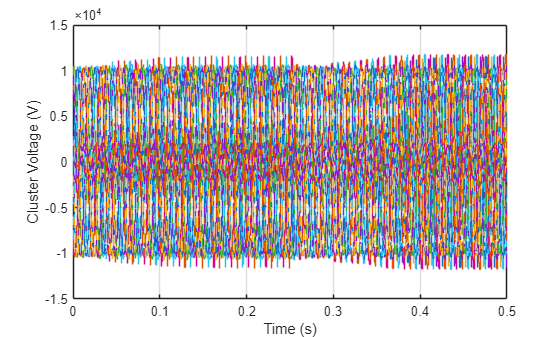

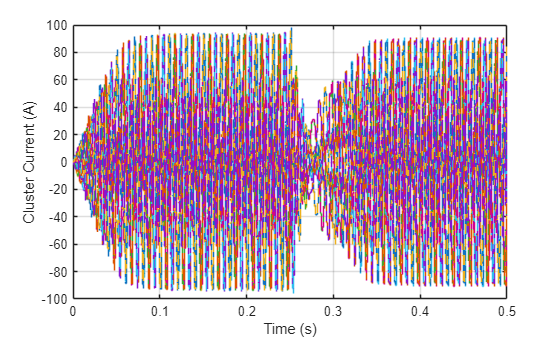

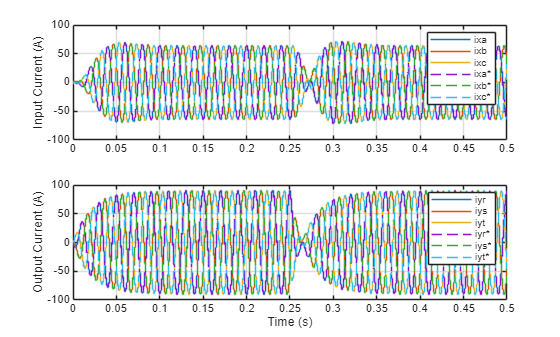

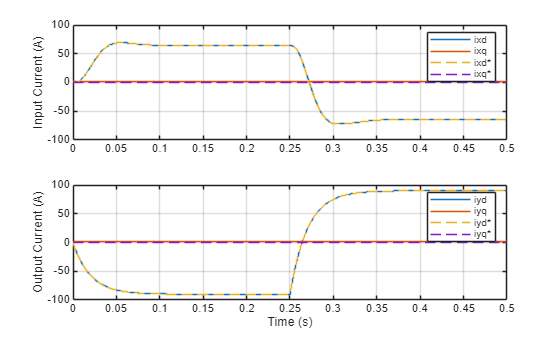

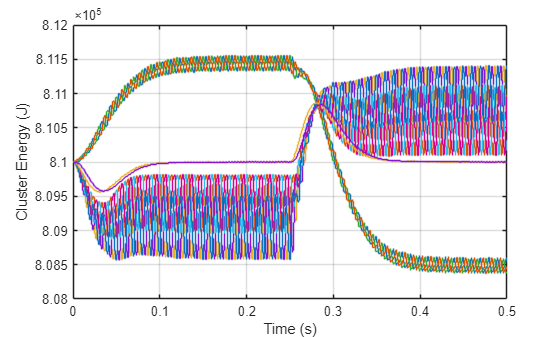

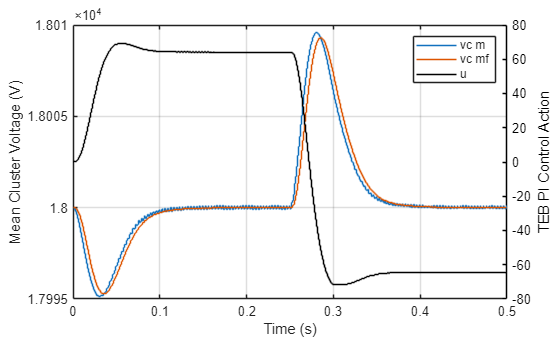

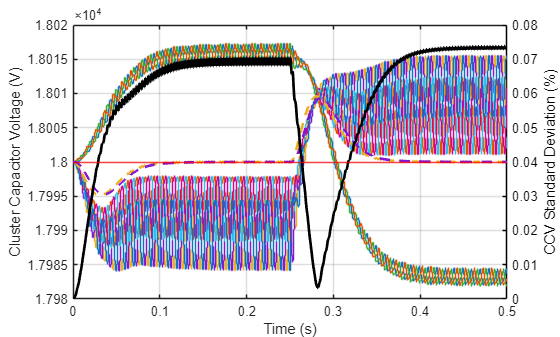

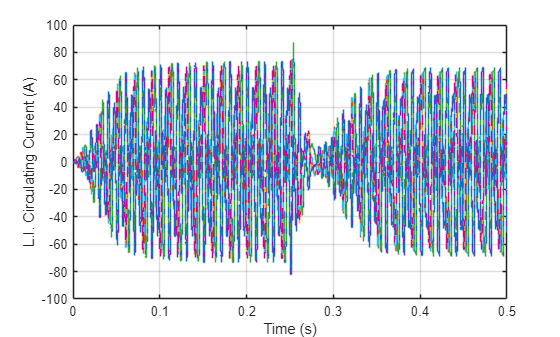

run("Plot.mlx")